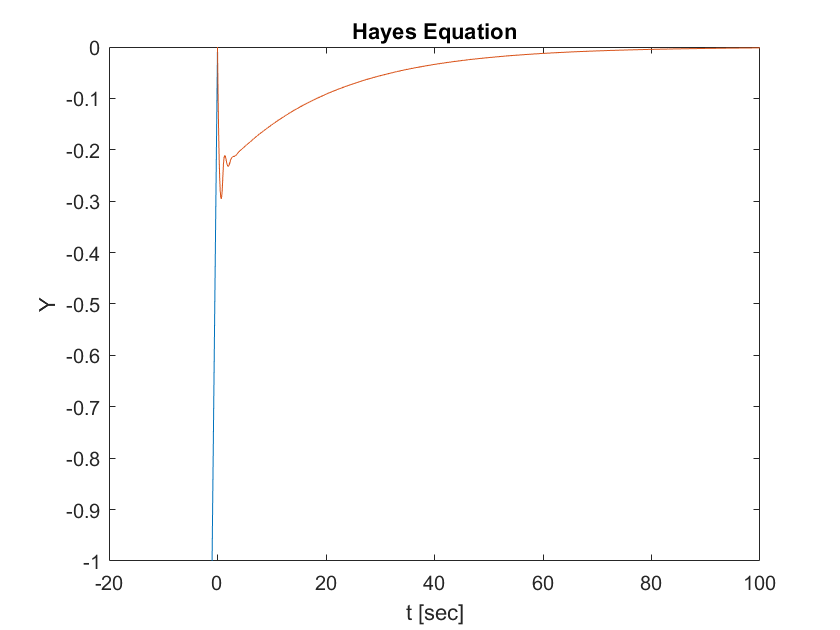

% Hayes delay differenctial equation is a most basic delay differential
% Equation.
%INPUT: History Function (Initial Condition, which is a function in DDEs
%case)
%OUTPUT : Equation solution.

clear all;
close all;

tau = 1;

tstart = 0;
tdelta = 0.1;
tend = 100;
tspan = tstart:tdelta:tend;

hist = tstart-tau:tdelta:tstart;
ic = @(t)t;

%Arbitarily chosen a and b.
a = -1.1;
b = 1;

sol = dde23(@(t,y,ytau)ddefunc(t,y,ytau,a,b),tau,ic,tspan);
y = deval(sol,tspan);

figure(1);
plot(hist,ic(hist));
hold on;
plot(tspan,y);
xlabel('t [sec]');
ylabel('Y');
title("Hayes Equation")

function dydt = ddefunc(t,y,ytau,a,b)
    dydt = a*y + b*ytau; %Hayes Equation
end